# Lecture 3 - Stabilizability

## Exercise 1

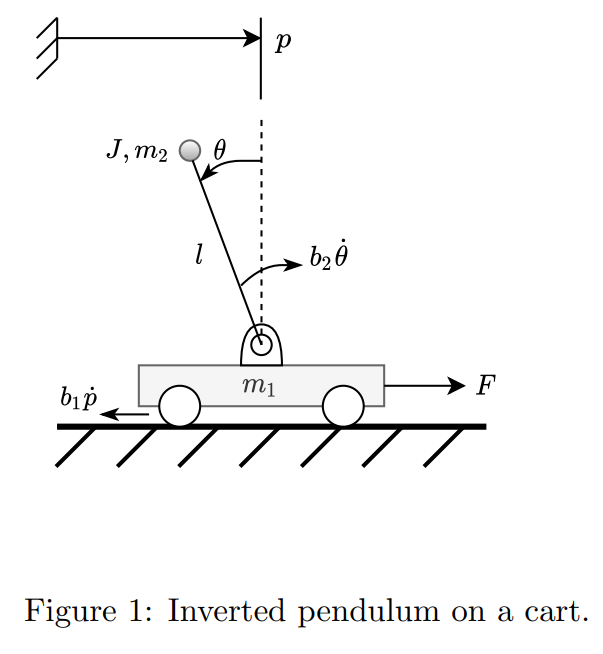

Consider the pendulum in Figure 1 with state $x={\left\lbrack \begin{array}{cccc}
p & \theta  & \dot{p}  & \dot{\theta} 
\end{array}\right\rbrack }^T$. When linearized in the upright position $\bar{x} =\left(0,0,0,0\right)$, the linear system matrices are given by

$A=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & \frac{{\textrm{gl}}^2 m_2^2 }{J_t M_t -m_2^2 l^2 } & \frac{-b_1 J_t }{J_t M_t -m_2^2 l^2 } & \frac{-b_2 {\textrm{lm}}_2 J_t }{J_t M_t -m_2^2 l^2 }\\
0 & \frac{M_t m_2 \textrm{gl}}{J_t M_t -m_2^2 l^2 } & \frac{-b_1 {\textrm{lm}}_2 }{J_t M_t -m_2^2 l^2 } & \frac{-b_2 M_t }{J_t M_t -m_2^2 l^2 }
\end{array}\right\rbrack$, $B=\left\lbrack \begin{array}{c}
0\\
0\\
\frac{J_t }{J_t M_t -m_2^2 l^2 }\\
\frac{{l\;m\;}_2 }{J_t M_t -m_2^2 l^2 }
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$ 

Use the following parameter values $m_1 =2$,$m_2 =1,J=0\ldotp 01,l=1,b_1 =b_2 =0\ldotp 1,g=9\ldotp 81$

Remember that $M_t =m_1 +m_2$ and $J_t =J+m_2 l^2$

### Simulate the system with initial condition $x_0 ={\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0
\end{array}\right\rbrack }^T$. You can use the command initial() in MATLAB. Is the system stable? If so, does it make any sense?

I will start by entering the values 

m1 = 2;     % Mass of the cart
m2 = 1;     % Mass of pendulum with center of mass at tip.
J = 0.01;   % Inertia
l = 1;      % Length of pendulum
b1 = 0.1;   % Friction of cart opposite of the force F
b2 = 0.1;   % Friction of pendulum opposite of the angle
g = 9.81;   % Gravity acceleration

Setting our mass total $M_t$ and interia total $J_t$

Mt = m1 + m2;   % Total mass
Jt = J + m2*l^2 % Total inertia

Jt = 1.0100

And setting our initial condition:

x0 = [0;0;0;0];

Compute our state space model

A = [0 0 1 0;
     0 0 0 1;
     0 (g*l^2*m2^2)/(Jt*Mt - m2^2*l^2) -b1*Jt/(Jt*Mt - m2^2*l^2) -b2*l*m2*Jt/(Jt*Mt - m2^2*l^2);
     0 Mt*m2*g*l / (Jt*Mt - m2^2*l^2) -b1*l*m2/(Jt*Mt - m2^2*l^2) -b2*Mt/(Jt*Mt - m2^2*l^2)];
B = [0; 0; Jt/(Jt*Mt - m2^2*l^2); l*m2/(Jt*Mt - m2^2*l^2)];
C = eye(4);

Now simulating the system:

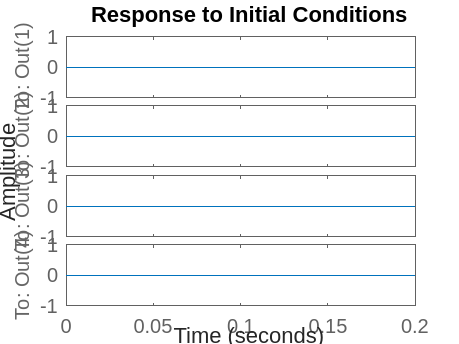

sys = ss(A,B,C,[]); % Could also be done using ODE45
initial(sys,x0)

This makes sense, becuase we say that the initial condition is 0 in position, but most importantly, it does not have any velocity, so therefore it starts in it's steady state. 

To determine if the system is stable we can look at the eigenvalues of A

eig(A)

ans =          0
   -3.8906
    3.7264
   -0.0333


Where we can see that the condition $\lambda_i \in \sigma \left(A\right)\subset {\mathbb{C}}_-$ does not hold i.e. $\mathrm{Re}\left(\lambda \right)<0\;\forall \lambda \in \sigma \left(A\right)$ does not hold. There are eigenvalues greater than 0, therefore the system is not stable, even though the system has reached steady state. 

### Simulate the system with new initial conditions $x_0 ={\left\lbrack \begin{array}{cccc}
0 & 0\ldotp 00001 & 0 & 0
\end{array}\right\rbrack }^T$. What happens now to the system when you simulate it?

First i define the new initial conditions:

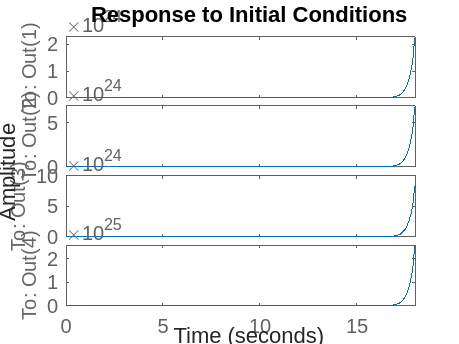

x0 = [0;0.0001;0;0];
initial(sys,x0)

This makes sense and follows the result of the last exercise, where we determined that the system is not stable. Even though the initial conditions are very close to the previous initial conditions, we now start with a slight angle offset in the pendulum, which entails that it will fall down, and therefore the system is unstable. 

### 3. Design a state feedback control law that stabilizes the system around the operating point, placing the closed-loop poles at $\left\lbrace -1\;,-2,-3,-4\right\rbrace$. You can use the place() command in MATLAB. NOTE: MATLAB assumes negative feedback, therefore you need to multiply the result with -1 as we assume positive feedback in the formulation.

First lets define the positions of the poles

p = [-1 -2 -3 -4];

Then we can find the gain matrix $K$ which gives us the state feedback control law 

K = -place(A,B,p)

K =     4.9664 -106.5306   10.4970  -30.5009


Where the control input $u=K\;x$, therefore the new state space model is:


$$\dot{x} =\mathrm{Ax}+\mathrm{Bu}\to \left(A+B\;K\right)x$$


We can check if the system is now stable, and see that the real parts of the poles in the system are now negative, where we set them.

eig(A+B*K)

ans =    -4.0000
   -3.0000
   -2.0000
   -1.0000


### 4. Simulate the system with the initial condition $x_0 ={\left\lbrack \begin{array}{cccc}
0 & 0\ldotp 1 & 0 & 0
\end{array}\right\rbrack }^T$

We set the initial condition:

x0 = [0; 0.1; 0; 0];

Now we set the new system. Note that the new system matrix $A$ (which is the one acting on $x$) which is now $\left(A+B\;K\right)x$ so therefore the new $A=A+B\;K$ and because we do not incorporate the $B$ twice.

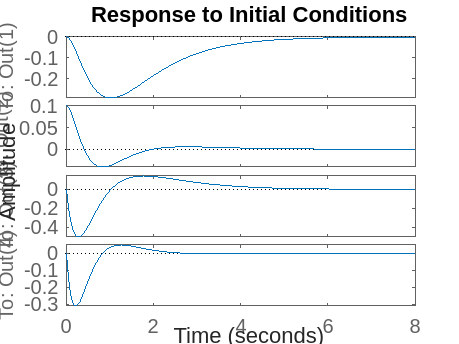

sys = ss(A+B*K,[],C,[]); % Could also be done using ODE45
initial(sys,x0)

### 5. Now try to design a new feedback control law, using the Linear Quadratic Regulator (LQR) method. You can use the lqr() command in matlab. Start by choosing $Q=\mathrm{diag}\left(1,1,1,1\right)$ and $R=1$. What does $Q$ and $R$ represent?

Q = diag([1 1 1 1]);
R = 1;

Since we are trying to compute a new control law, we should use the original system again, and not the other control law. 

sys = ss(A,B,C,[]); % Could also be done using ODE45
[K, S, P] = lqr(sys, Q,R);

Here the optimal gain matrix $K$ is returned, and the solution $S$to the associated algebraic Ricatti Equation, and the closed loop poles.

$Q\ge 0$ (positive semidefinite) and $R>0$ (positive definite) is weight matrices on the states and inputs respectively. 

Based on the optimal control problem:


$$\min_{u=u\left(t\right)} \int_0^T \left({y\left(s\right)}^* Q\;y\left(s\right)+{u\left(s\right)}^* R\;u\left(s\right)\right)\;\mathrm{ds}$$


And since $y=C\;x$ and $C=I$ we have $x^* Q\;x+u^* R\;u$

eig(A-B*K);

Now we can do the same as before with $\dot{x} =\mathrm{Ax}+\mathrm{Bu}\to \left(A+\mathrm{BK}\right)x+0u$

Now we place the poles again based on the solution poles. 

**Note** the inversed sign. 

We can now see that the system is stable, and it makes sense. 

### 6. Simulate the closed loop-response and compare the result obtained with the pole placement method. 

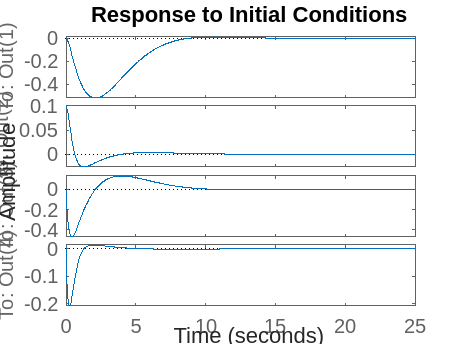

sys = ss(A-B*K,[],C,[]); % Could also be done using ODE45
initial(sys,x0)

We can see that the transient response is longer than the pole placement method, which entails a need for better tuning of the system. 

### 7. Tune the $Q$ and $R$ values to get a "better" response than the poleplacement method. 

Since this is a special case where $C=I$ we can use a common tuning method known as Bryson's rule

$Q_{\mathrm{ii}} =\frac{1}{\max \left(x_i^2 \right)}$ and $R_{\mathrm{ii}} =\frac{1}{\max \left(u_i^2 \right)}$

In this rule the $x_i$ is the $i^{\prime } \mathrm{th}$ state value in the state vector $x$. same goes for $u$.

However we just use manual tuning. 

Qtuned = diag([5,100,25,10]);
Rtuned = 1;
[K, S, P] = lqr(sys, Qtuned,Rtuned);
initial(sys,x0)

### 8. Try to augment the original matrix $A$ by $20%$ and simulate the closed-loop response again and compare it to the previous result. Remember you are not allowed to redesing the control-law, i.e. $K$ is the same as before, computed from the original $A$. Is the system still stable?

We scale the original A with $20%$

Aaug = A.*1.2

Aaug =          0         0    1.2000         0
         0         0         0    1.2000
         0    5.7990   -0.0597   -0.0597
         0   17.3970   -0.0591   -0.1773


eig(Aaug)

ans =          0
   -4.6688
    4.4717
   -0.0400


K = -place(A,B,p)

K =     4.9664 -106.5306   10.4970  -30.5009


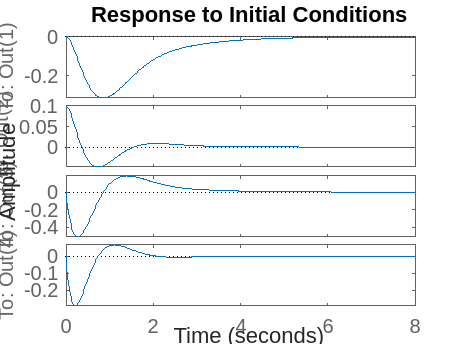

sys = ss(Aaug+B*K,[],C,[]); % Could also be done using ODE45
initial(sys,x0)

Even thoug the system is not stable, it still converges with the original gain Matrix $K$ based on poleplacement. 

Usually you will not have a stable system. 

### 9. Test the controller on the nonlinear simulation model of the inverted pendulum system. You can use Simulink for the purpose, it sometimes makes it easier to alter the simulation. 

## Exercise 2

clear all

Consider the same satelite system from laster exercise session as sketched in Figure 2. 

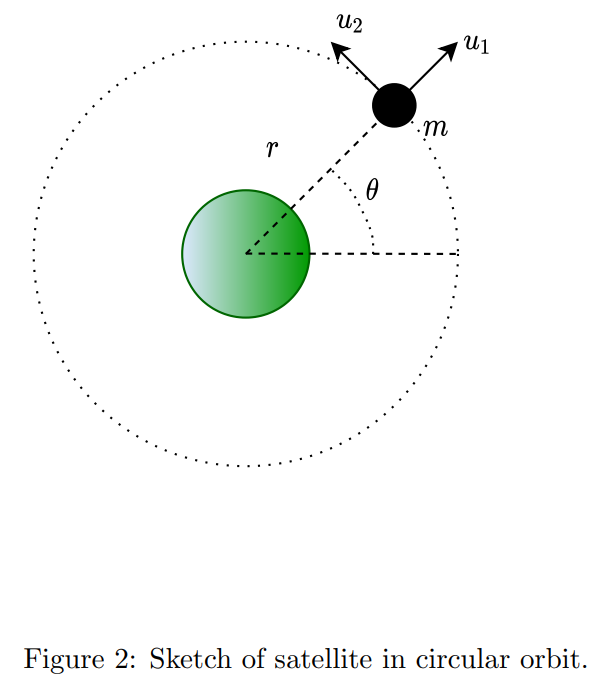

The satelite is of mass $m$ with thrust in the radial direction $u_1$ and in the tangential direction $u_2$. The states and inputs are given by 


$$x=\left\lbrack \begin{array}{c}
r\\
\theta \\
\dot{r} \\
\dot{\theta} 
\end{array}\right\rbrack$$



$$u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Linearized in the operating point $\bar{x} =\left(\bar{r} ,\bar{\theta} ,0,\bar{\dot{\theta} } \right)$, the linear state space system is given by


$$\dot{x} =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
3{\bar{\dot{\theta} } }^2  & 0 & 0 & 2\bar{r} \bar{\dot{\theta} } \\
0 & 0 & -2\bar{\dot{\theta} }  & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
\frac{1}{m} & 0\\
0 & \frac{1}{\left(m\;\bar{r} \right)}
\end{array}\right\rbrack u$$


In contrary to last time, we assume that all states are fed back i.e., 


$$y=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack x$$


### 1. Design a feedback controller for the case where both $u_1$ and $u_2$are available and simulate it in MATLAB. Choose different initial conditions

For this exercise we just choose a random linearization operating point $\bar{x}$. In general it would be smart to use the equilbrium point to linearize the system around, however this is not evident initially. 

let 

xbar = [1; 1; 1; 1];

Let the mass $m$ of the satelite be 

m = 10;

And lets initialize the control matrix 

A = [0 0 1 0;
     0 0 0 1;
     3*xbar(4)^2 0 0 2*xbar(1)*xbar(4);
     0 0 -2*xbar(4) 0];
B =[0 0;
    0 0;
    1/m 0;
    0 1/(m*xbar(1))];

Lets set the initial conditions $x_0$to be 

x0 = [1;2;5;10];

And let the control input vector $u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$

u1 = 0;
u2 = 0;
u = [u1; 
     u2];

and $C=I\in R^4$

C = eye(4);

Then by using pole placement, with poles

p = [-1 -2 -3 -4];

Then we can find the gain matrix $K$ which gives us the state feedback control law 

K = -place(A,B,p)

K =  -150.0000         0  -70.0000  -20.0000
         0  -20.0000   20.0000  -30.0000


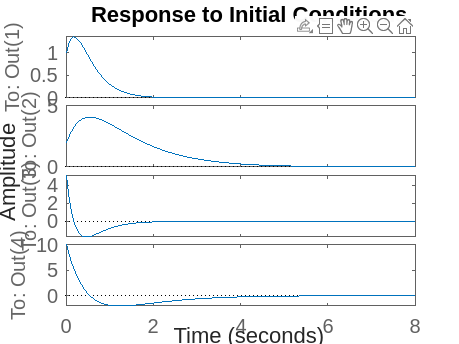

sys = ss(A+B*K,[],C,[]); % Could also be done using ODE45
cinitial(sys,x0)